# 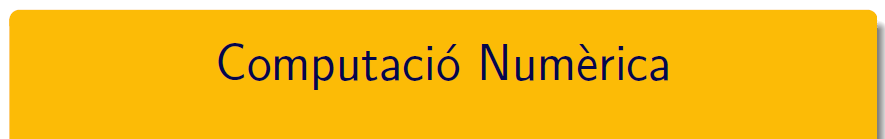

=====================================================================================

# Autoevaluació 

## Entrega AA3                                                                                    Marta Granero I Martí

## EXERCICI 1 - Resolució de sistemas d'equacions no lineals

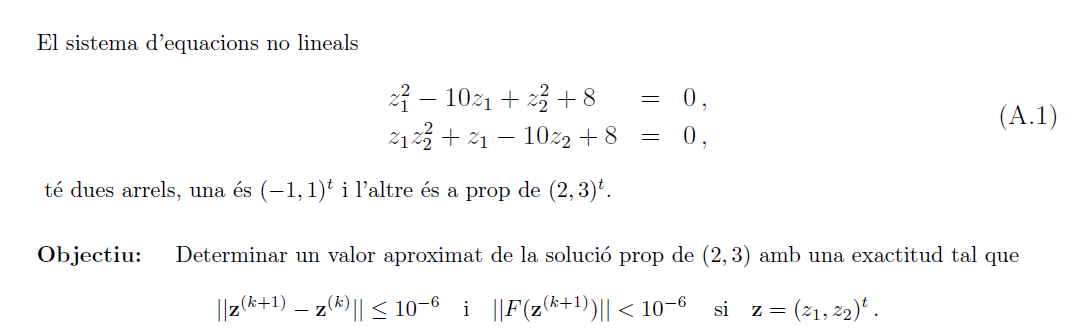

1a) Aproximeu totes les solucions del sistema (A.1) gràficament.

%Procedim a la resolució gràfica

F1 = @(x,y) x^2-10*x + y^2 + 8; %z1 = x, z2 = y
F2 = @(x,y) x*y^2 + x - 10*y + 8;

fimplicit(F1,[-11 11 -11 11],':r','LineWidth',2)

hold on
fimplicit(F2,[-11 11 -11 11],'--g','LineWidth',2)

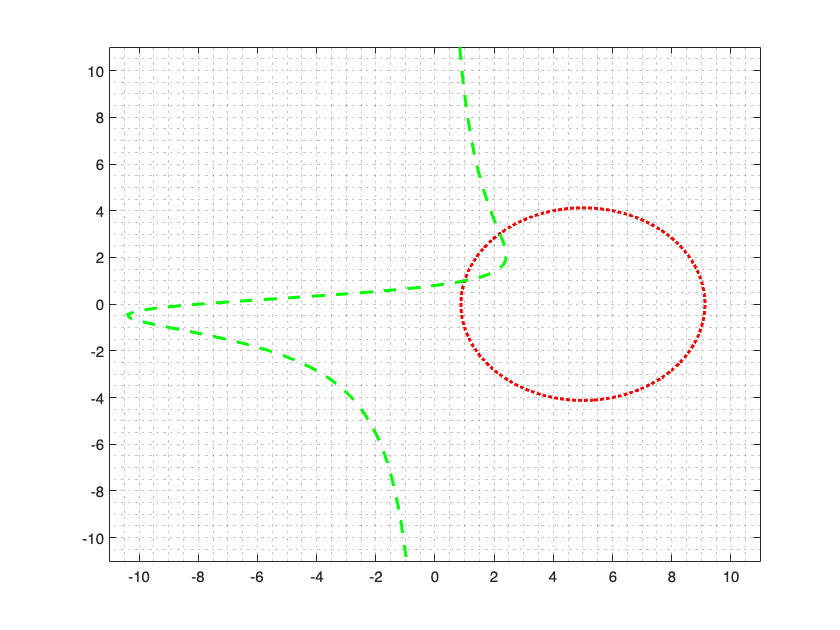

grid minor

hold off

%Solució bona es fa servir en apartats posteriors per calcular el nombre de
%xifres signficatives
x0=[2;3];
[x, ~] = fsolve(@myfun,x0);


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


myfun(x);

valorBo = x;

1b) Fent ús del mètode de **Newton** i prenent $x_0=(2,3)
$. Presenteu les iteracions en una taula.

%Mètode de Newton prenent 6 iteracions
%taula
format longG
x0 =[2;3];
F  = @(x,y)[x^2-10*x + y^2 + 8; x*y^2 + x - 10*y + 8];
F(x0(1),x0(2));
JF = @(x,y)[2*x-10, 2*y; 1+y^2, 2*x*y-10];

for k=1:200
    y  = linsolve(JF(x0(1),x0(2)),(-F(x0(1),x0(2))));
    x0 = x0+y;

    res(k).y = y;
    res(k).x0 = x0;
    res(k).decimalsCorrectes = min(abs(valorBo'-x0'));
end

res %taula on es mostren tambe els decimals correctes

res = 1×200 struct array with fields:
    y
    x0
    decimalsCorrectes



tolF = norm(F(x0(1),x0(2)),'inf');

tolX = norm(y,'inf');

disp(['Solució = ',num2str(x0')])

Solució = 2.1934      3.0205


disp(['tolF = ',num2str(tolF)])

tolF = 3.5527e-15


disp(['tolX = ',num2str(tolX)])

tolX = 4.5297e-16


disp(['Iteracions = ',num2str(k)])

Iteracions = 200



%Obtenim amb 200 iteracions 9 decimals correctes i és un mètode convergent

1c) Fent ús del mètode de **Newton modificat** i prenent $x_0=(2,3)
$. Presenteu les iteracions en una taula.

valor = zeros(200,2);

for k = 1:200
    valor(k,:) = newtonModificat(F,JF,x0,k,tolF,tolX,5); %30 = #iteracions fixes
    if k > 1 && valor(k,1) == valor(k-1,1) && valor(k,2) == valor(k-1,2) %condició parada
        break;
    end
end

Solució = 2.1934      3.0205
tolF = 5.0243e-15
tolX = 3.6898e-16
Iteracions = 1
Solució = 2.1934      3.0205
tolF = 3.5527e-15
tolX = 4.6213e-16
Iteracions = 2
Solució = 2.1934      3.0205
tolF = 3.5527e-15
tolX = 4.7574e-16
Iteracions = 3
Solució = 2.1934      3.0205
tolF = 5.0243e-15
tolX = 3.6898e-16
Iteracions = 4
Solució = 2.1934      3.0205
tolF = 3.5527e-15
tolX = 4.6213e-16
Iteracions = 5
Solució = 2.1934      3.0205
tolF = 3.5527e-15
tolX = 4.7574e-16
Iteracions = 6
Solució = 2.1934      3.0205
tolF = 5.0243e-15
tolX = 3.6898e-16
Iteracions = 7
Solució = 2.1934      3.0205
tolF = 3.5527e-15
tolX = 4.6213e-16
Iteracions = 8
Solució = 2.1934      3.0205
tolF = 3.5527e-15
tolX = 4.7574e-16
Iteracions = 9
Solució = 2.1934      3.0205
tolF = 5.0243e-15
tolX = 3.6898e-16
Iteracions = 10
Solució = 2.1934      3.0205
tolF = 3.5527e-15
tolX = 4.6213e-16
Iteracions = 11
Solució = 2.1934      3.0205
tolF = 3.5527e-15
tolX = 4.7574e-16
Iteracions = 12
Solució = 2.1934      3.0205
tolF = 5


array2table(valor(1:k,:), "VariableNames", {'x', 'y'})

ans = 200×2 table
           x                   y        
    ________________    ________________

    2.19343941541531    3.02046646812303
    2.19343941541531    3.02046646812303
    2.19343941541531    3.02046646812303
    2.19343941541531    3.02046646812303
    2.19343941541531    3.02046646812303
    2.19343941541531    3.02046646812303
    2.19343941541531    3.02046646812303
    2.19343941541531    3.02046646812303
    2.19343941541531    3.02046646812303
    2.19343941541531    3.02046646812303
    2.19343941541531    3.02046646812303
    2.19343941541531    3.02046646812303
    2.19343941541531    3.02046646812303
    2.19343941541531    3.02046646812303
    2.19343941541531    3.02046646812303
    2.19343941541531    3.02046646812303


decimalsCorrectes = min(abs(valorBo' - valor(k,:)))

decimalsCorrectes =       1.21922916207495e-10



%Obtenim amb 200 iteracions 9 decimals correctes i és un mètode convergent

1d) Fent ús del mètode ** de Jacobi** i prenent $x_0=(2,3)
$. Presenteu les iteracions en una taula.

valor = zeros(200,2);
for k = 1:200
    valor(k,:) = newtonJacobi(F,JF,x0,k,tolF,tolX);
    if k > 1 && valor(k,1) == valor(k-1,1) && valor(k,2) == valor(k-1,2) %condició parada
        break;
    end
end

Solució = 2.1934      3.0205
tolF = 5.3291e-15
tolZ = 1.093e-15
Iteracions = 1
Solució = 2.1934      3.0205
tolF = 1.0805e-14
tolZ = 9.494e-16
Iteracions = 2
Solució = 2.1934      3.0205
tolF = 1.986e-14
tolZ = 3.2942e-15
Iteracions = 3
Solució = 2.1934      3.0205
tolF = 3.6231e-14
tolZ = 3.6487e-15
Iteracions = 4
Solució = 2.1934      3.0205
tolF = 6.5509e-14
tolZ = 1.1003e-14
Iteracions = 5
Solució = 2.1934      3.0205
tolF = 1.1638e-13
tolZ = 1.2203e-14
Iteracions = 6
Solució = 2.1934      3.0205
tolF = 2.1913e-13
tolZ = 3.5256e-14
Iteracions = 7
Solució = 2.1934      3.0205
tolF = 3.9577e-13
tolZ = 4.0476e-14
Iteracions = 8
Solució = 2.1934      3.0205
tolF = 7.3402e-13
tolZ = 1.2002e-13
Iteracions = 9
Solució = 2.1934      3.0205
tolF = 1.3277e-12
tolZ = 1.3578e-13
Iteracions = 10
Solució = 2.1934      3.0205
tolF = 2.47e-12
tolZ = 4.0288e-13
Iteracions = 11
Solució = 2.1934      3.0205
tolF = 4.4672e-12
tolZ = 4.5618e-13
Iteracions = 12
Solució = 2.1934      3.0205
tolF = 8.2934


array2table(valor(1:k,:), "VariableNames", {'x', 'y'})

ans = 123×2 table
           x                   y        
    ________________    ________________

    2.19343941541531    3.02046646812303
    2.19343941541531    3.02046646812303
    2.19343941541531    3.02046646812304
    2.19343941541531    3.02046646812304
    2.19343941541531    3.02046646812302
     2.1934394154153    3.02046646812303
     2.1934394154153    3.02046646812306
    2.19343941541534    3.02046646812305
    2.19343941541533    3.02046646812293
     2.1934394154152    3.02046646812298
    2.19343941541525    3.02046646812338
    2.19343941541568    3.02046646812323
    2.19343941541552    3.02046646812188
    2.19343941541407    3.02046646812238
     2.1934394154146    3.02046646812689
    2.19343941541946    3.02046646812523


decimalsCorrectes = min(abs(valorBo' - valor(k,:)))

decimalsCorrectes =           1.19343941553723



%Amb 123 iteracions no obtenim cap decimal correcte i veiem que
%ens troba la segona solució al sistema que es troba al punt [1,1]. Veiem
%que és un mètode convergent cap a la solució [1,1] a partir del valor inicial [2,3]

1e) Fent ús del mètode de** Gauss-Seidel** i prenent $x_0=(2,3)
$. Presenteu les iteracions en una taula.

valor = zeros(200,2);
for k = 1:200
    valor(k,:) = newtonGaussSeidel(F,JF,x0,k,tolF,tolX);
    if k > 1 && valor(k,1) == valor(k-1,1) && valor(k,2) == valor(k-1,2) 
        break;
    end
end

Solució = 2.1934      3.0205
tolF = 3.5527e-15
tolZ = 4.5297e-16
Iteracions = 1
Solució = 2.1934      3.0205
tolF = 3.5527e-15
tolZ = 4.5297e-16
Iteracions = 2
Solució = 2.1934      3.0205
tolF = 3.5527e-15
tolZ = 4.5297e-16
Iteracions = 3
Solució = 2.1934      3.0205
tolF = 3.5527e-15
tolZ = 4.5297e-16
Iteracions = 4
Solució = 2.1934      3.0205
tolF = 3.5527e-15
tolZ = 4.5297e-16
Iteracions = 5
Solució = 2.1934      3.0205
tolF = 3.5527e-15
tolZ = 4.5297e-16
Iteracions = 6
Solució = 2.1934      3.0205
tolF = 3.5527e-15
tolZ = 4.5297e-16
Iteracions = 7
Solució = 2.1934      3.0205
tolF = 3.5527e-15
tolZ = 4.5297e-16
Iteracions = 8
Solució = 2.1934      3.0205
tolF = 3.5527e-15
tolZ = 4.5297e-16
Iteracions = 9
Solució = 2.1934      3.0205
tolF = 3.5527e-15
tolZ = 4.5297e-16
Iteracions = 10
Solució = 2.1934      3.0205
tolF = 3.5527e-15
tolZ = 4.5297e-16
Iteracions = 11
Solució = 2.1934      3.0205
tolF = 3.5527e-15
tolZ = 4.5297e-16
Iteracions = 12
Solució = 2.1934      3.0205
tolF = 3


array2table(valor(1:k,:), "VariableNames", {'x', 'y'})

ans = 48×2 table
           x                   y        
    ________________    ________________

    2.19343941541531    3.02046646812303
    2.19343941541531    3.02046646812304
    2.19343941541531    3.02046646812303
     2.1934394154153    3.02046646812306
    2.19343941541534    3.02046646812295
    2.19343941541521    3.02046646812333
    2.19343941541562    3.02046646812206
    2.19343941541426    3.02046646812631
    2.19343941541884    3.02046646811205
    2.19343941540349    3.02046646815985
    2.19343941545493    3.02046646799963
     2.1934394152825    3.02046646853666
    2.19343941586046    3.02046646673662
    2.19343941392323    3.02046647277001
    2.19343942041646    3.02046645254729
    2.19343939865244    3.02046652032988


decimalsCorrectes = min(abs(valorBo' - valor(k,:)))

decimalsCorrectes =           1.19343941553723



%Amb 48 iteracions no obtenim cap decimal correcte tot i així veiem que
%ens troba la segona solució al sistema que es troba al punt [1,1]. 
% És un mètode convergent cap a la solució [1,1] a partir del valor inicial [2,3]

1f) Fent ús de** Fsolve ** prenent $x_0=(2,3)
$. Presenteu les iteracions en una taula.

%Sense opcions
x0=[2;3];
[x, ~] = fsolve(@myfun,x0);


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


myfun(x);

valorBo = x;

%Mètode amb iteracions i opcions configurables
clear vars
options = optimoptions('fsolve','Display','iter','StepTolerance',5e-15,'OptimalityTolerance',5e-15)

options =   fsolve options:

   Options used by current Algorithm ('trust-region-dogleg'):
   (Other available algorithms: 'levenberg-marquardt', 'trust-region')

   Set properties:
                     Display: 'iter'
         OptimalityTolerance: 5e-15
               StepTolerance: 5e-15

   Default properties:
                   Algorithm: 'trust-region-dogleg'
              CheckGradients: 0
    FiniteDifferenceStepSize: 'sqrt(eps)'
        FiniteDifferenceType: 'forward'
           FunctionTolerance: 1e-06
      MaxFunctionEvaluations: '100*numberOfVariables'
               MaxIterations: 400
                   OutputFcn: []
                     PlotFcn: []
    SpecifyObjectiveGradient: 0
                    TypicalX: 'ones(numberOfVariables,1)'
                 UseParallel: 0

   

x0 = [2,3];
[~, fval] = fsolve(@myfun,x0,options)


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3               5                            26               1
     1          6      0.00265129       0.196419          0.346               1
     2          9     2.87311e-08     0.00736061        0.00132               1
     3         12     3.55929e-18    2.08213e-05       1.62e-08               1
     4         15     1.26218e-29    2.21674e-10        3.6e-14               1

Equation solved, inaccuracy possible.

The vector of function values is near zero, as measured by the value
of the function tolerance. However, the last step was ineffective.

<

fval =                          0       3.5527136788005e-15


1g) Fent ús del** mètode de la iteració simple ** prenent una funció d'iteració G adient. Verifiqueu la convergència a priori del vostre mètode abans de calcular les iteracions. Preneu $x_0=(2,3)
$ si és possible, altrement raoneu la el·lecció de $x_0
$. Presenteu les iteracions en una taula.

format longG;
G1 = @(x,y)(x^2)/10 + (y^2)/10 + 0.8; %z1^2/10 + z2^2/10 +8/10
G2 = @(x,y) sqrt((-x+10*y-8)/x); %(x*y^2)/10 + x/10 + 0.8; % converg

x0 = [2;3];

for k=1:40
    resI(k).x0(1) = G1(x0(1),x0(2));
    resI(k).x0(2) = G2(x0(1),x0(2));
    %disp([k,x0']);
    resI(k).decimalsCorrectes = min(abs(valorBo'-x0'));
end

tolF = 10^(-6);

resI

resI = 1×40 struct array with fields:
    x0
    decimalsCorrectes



disp(['Solució = ',num2str(x0')])

Solució = 2  3


disp(['tolF = ',num2str(tolF)])

tolF = 1e-06


disp(['Iteracions = ',num2str(k)])

Iteracions = 40



%Si aïllem G1 i de G2 de la forma que veiem a continuació:
% G1 = @(x,y)(x^2)/10 + (y^2)/10 + 0.8;
% G2 = @(x,y) (x*y^2)/10 + x/10 + 0.8; 
% el mètode és convergent a partir del punt[2,3] a la solució [1,1].
% 
% Per trobar la descomposició adient per G i que el mètode sigui convergent a la solució que volem,
% hem de seguir provant possibles combinacions per aïllar G1 i G2 correctament.
% 
% Finalment les aïllacions correctes són:
%G1 = @(x,y)(x^2)/10 + (y^2)/10 + 0.8;
%G2 = @(x,y)sqrt((-x+10*y-8)/x)

%Un cop hem trobat la combinació correcta, obtenim 6 xifres decimals
%correctes i efectivament és un mètode convergent.

1h) Conclusions: comenta les diferències trobades. Quants decimals correctes obteniu?

El nombre de decimals correctes obtinguts es troba a cada apartat respecivament.

## EXERCICI 2 - Derivació i ajust de corbes 

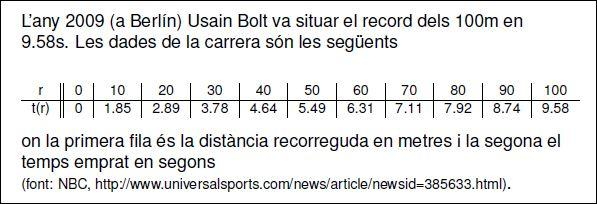

Calculeu una aproximació de la velocitat i l'acceleració en la carrera a partir de les dades de la taula.

%dades
r  = [0:10:100];
tr = [0 1.85 2.89 3.78 4.64 5.49 6.31 7.11 7.92 8.74 9.58];
%disp([r;tr]')
dades = array2table([r;tr]', 'VariableNames', {'Distància (m)', 'Temps (s)'})

dades = 11×2 table
    Distància (m)    Temps (s)
    _____________    _________

           0              0   
          10           1.85   
          20           2.89   
          30           3.78   
          40           4.64   
          50           5.49   
          60           6.31   
          70           7.11   
          80           7.92   
          90           8.74   
         100           9.58   



%càlcul aproximació [v,a] on fem servir per cadascun la fórmula enrere
v = [];
a = [];
for i=2:11
    v(i)=(r(i)-r(i-1))/(tr(i)-tr(i-1));
    a(i)=(v(i)-v(i-1))/(tr(i)-tr(i-1));
end

resultat = array2table([r;tr;v;a]', 'VariableNames',{'Distància (m)', 'Temps (s)', 'Velocitat (m/s)', 'Acceleració (m/s^2)'})

resultat = 11×4 table
    Distància (m)    Temps (s)    Velocitat (m/s)     Acceleració (m/s^2)
    _____________    _________    ________________    ___________________

           0              0                      0                     0 
          10           1.85       5.40540540540541       2.9218407596786 
          20           2.89       9.61538461538461      4.04805693267232 
          30           3.78       11.2359550561798      1.82086566381479 
          40           4.64       11.6279069767442     0.455758047167916 
          50           5.49       11.7647058823529     0.160939888951466 
          60           6.31       12.1951219512195     0.524897644959254 
          70           7.11                   12.5     0.381097560975585 
          80           7.92       12.3456790123457    -0.190519737844821 
          90           8.74

Feu una representació gràfica dels valors obtinguts.

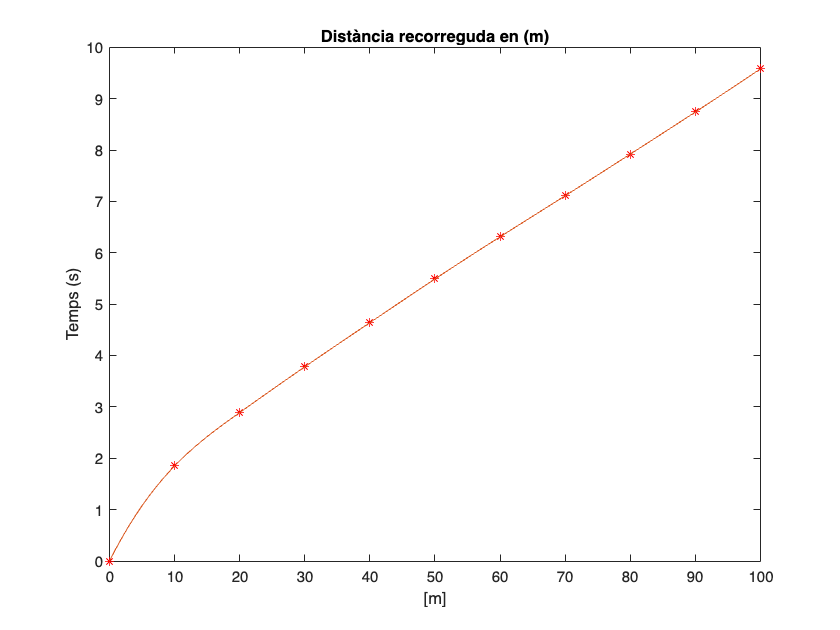

%representació de la distància
novaX = 0:1:100;
S = spline(r,tr,novaX);
plot(r,tr,'r*',novaX,S)

xlabel('[m]')
ylabel('Temps (s)');
title('Distància recorreguda en (m)')
hold off

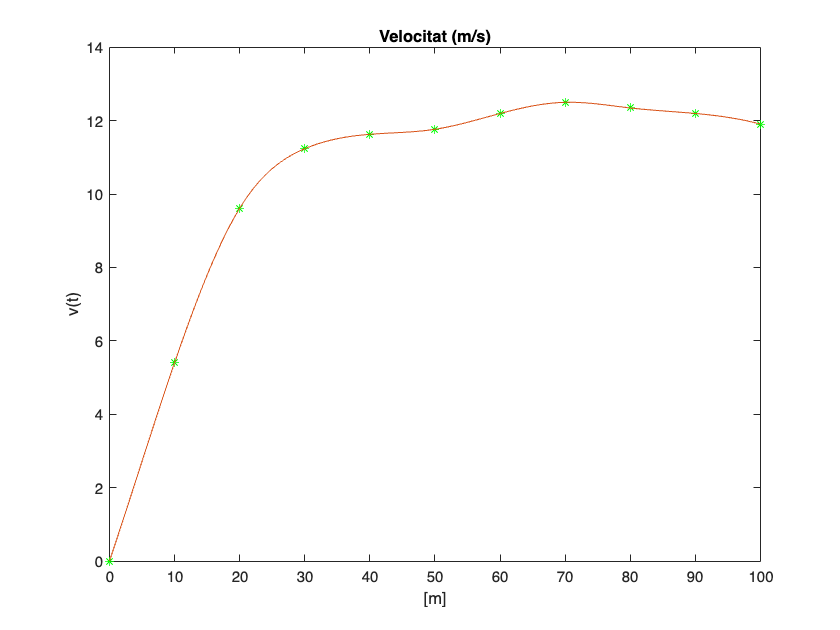


%representació de la velocitat
Sv = spline(r,v,novaX);
plot(r,v,'g*',novaX,Sv)

xlabel('[m]')
ylabel('v(t)');
title('Velocitat (m/s)')
hold off


%representació de l'acceleració
Sa = spline(r,a,novaX);
plot(r,a,'b*',novaX,Sa)

xlabel('[m]')
ylabel('a(t)');
title('Acceleració (m/s^2)')
hold off

## EXERCICI 3 - Interpolació 

Obteniu una corba que ajusti les dades de la taula següent per als diferents mètodes explicats en les classes: polinomica, spline lineal, spline cúbic. 

x = [0.9,1.3,1.9,2.1,2.6,3.0,3.9,4.4,4.7,5.0,6.0,7.0,8.0,9.2,10.5,11.3,11.6,12.0,12.6,13.0,13.3];
y = [1.3, 1.5, 1.85, 2.1, 2.6, 2.7, 2.4, 2.15 2.05, 2.1, 2.25, 2.3, 2.25, 1.95, 1.4, 0.9,0.7, 0.6, 0.5, 0.4, 0.25];
%scatter(x, y)
%disp([x,y]);
%plot(x,y);

%interpolació polinomica fent servir polyinterp
z  = [0:20]; 
pi = polyinterp(x,y,z);
plot(z,pi,x,y,'*r','LineWidth',2)
grid on
ylabel('Valors a la y')
xlabel('Valors a la x')
title('Polinomi interpolador a partir de polyinterp')
xlim([0 14])
ylim([0 3])
hold off

%spline lineal
z  = [0:20]; 
pz = interp1(x,y,z);
plot(z,pz,x,y,'*r','LineWidth',2)

grid on
ylabel('Valors a la y')
xlabel('Valors a la x')
title('Spline lineal (interpolació lineal a trossos)')
hold off

%spline cúbica
x = [0.9,1.3,1.9,2.1,2.6,3.0,3.9,4.4,4.7,5.0,6.0,7.0,8.0,9.2,10.5,11.3,11.6,12.0,12.6,13.0,13.3];
y = [1.3, 1.5, 1.85, 2.1, 2.6, 2.7, 2.4, 2.15 2.05, 2.1, 2.25, 2.3, 2.25, 1.95, 1.4, 0.9,0.7, 0.6, 0.5, 0.4, 0.25];

z  = [0:20]; 
pc = interp1(x,y,z, 'pchip');
plot(z,pc,x,y,'*r','LineWidth',2)

grid on
ylabel('Valors a la x')
xlabel('Valors a la y')
title('Cúbica a trossos - Spline preserving')
xlim([0 14])
ylim([0 3])
hold off

%fent servir polyfit
%disp([x; y]);
grau = length(x)-1;
p = polyfit(x,y,grau);

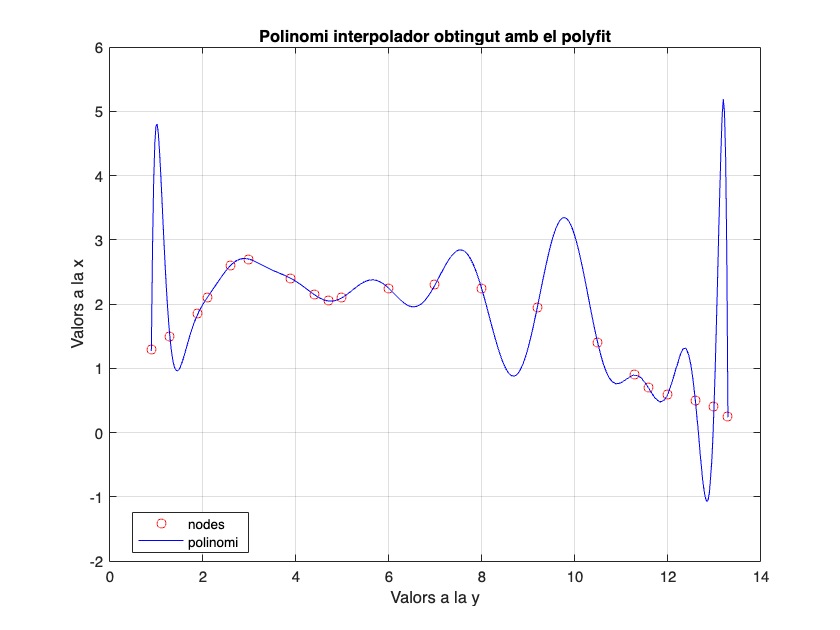

u = linspace(x(1),x(end),500);
v = polyval(p,u);
plot(x,y,'ro',u,v,'b-')
grid on
ylabel('Valors a la x')
xlabel('Valors a la y')
title('Polinomi interpolador obtingut amb el polyfit')
legend('nodes','polinomi','Location','best')
hold off

**Les dades són del llibre Numerical Analysis, Burden&Faires, per la imatge **

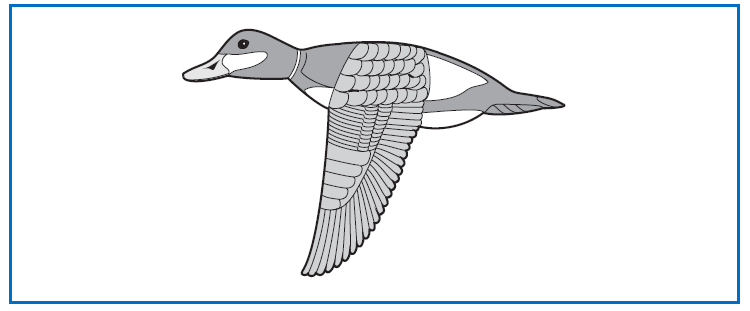

## EXERCICI 4 - Integració numèrica

Doneu una aproximació de l'area de la regió delimitada per la vostra ma.  Referència: [https://es.mathworks.com/moler/chapters.html](https://es.mathworks.com/moler/chapters.html)

**Apartat 1. **

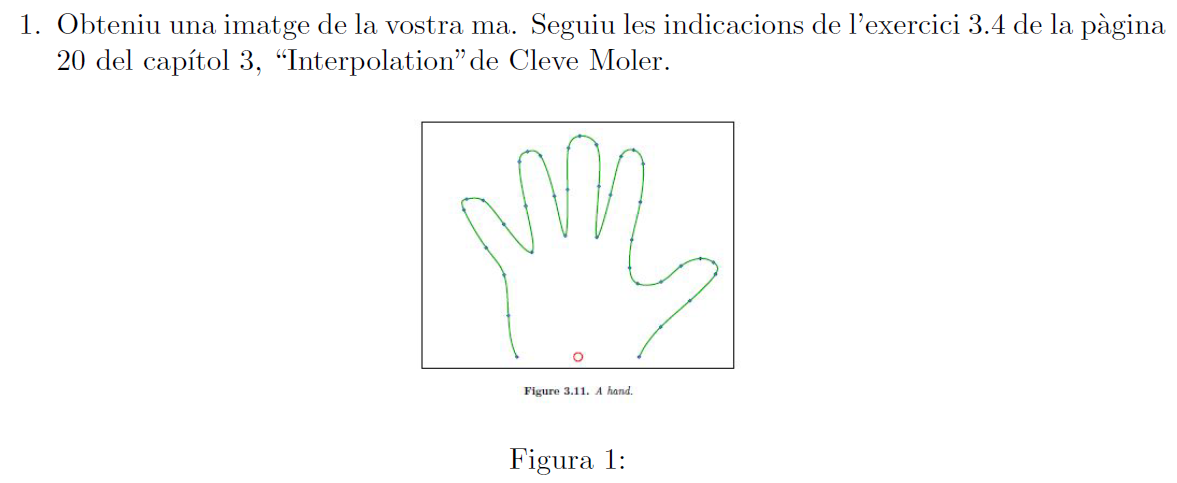

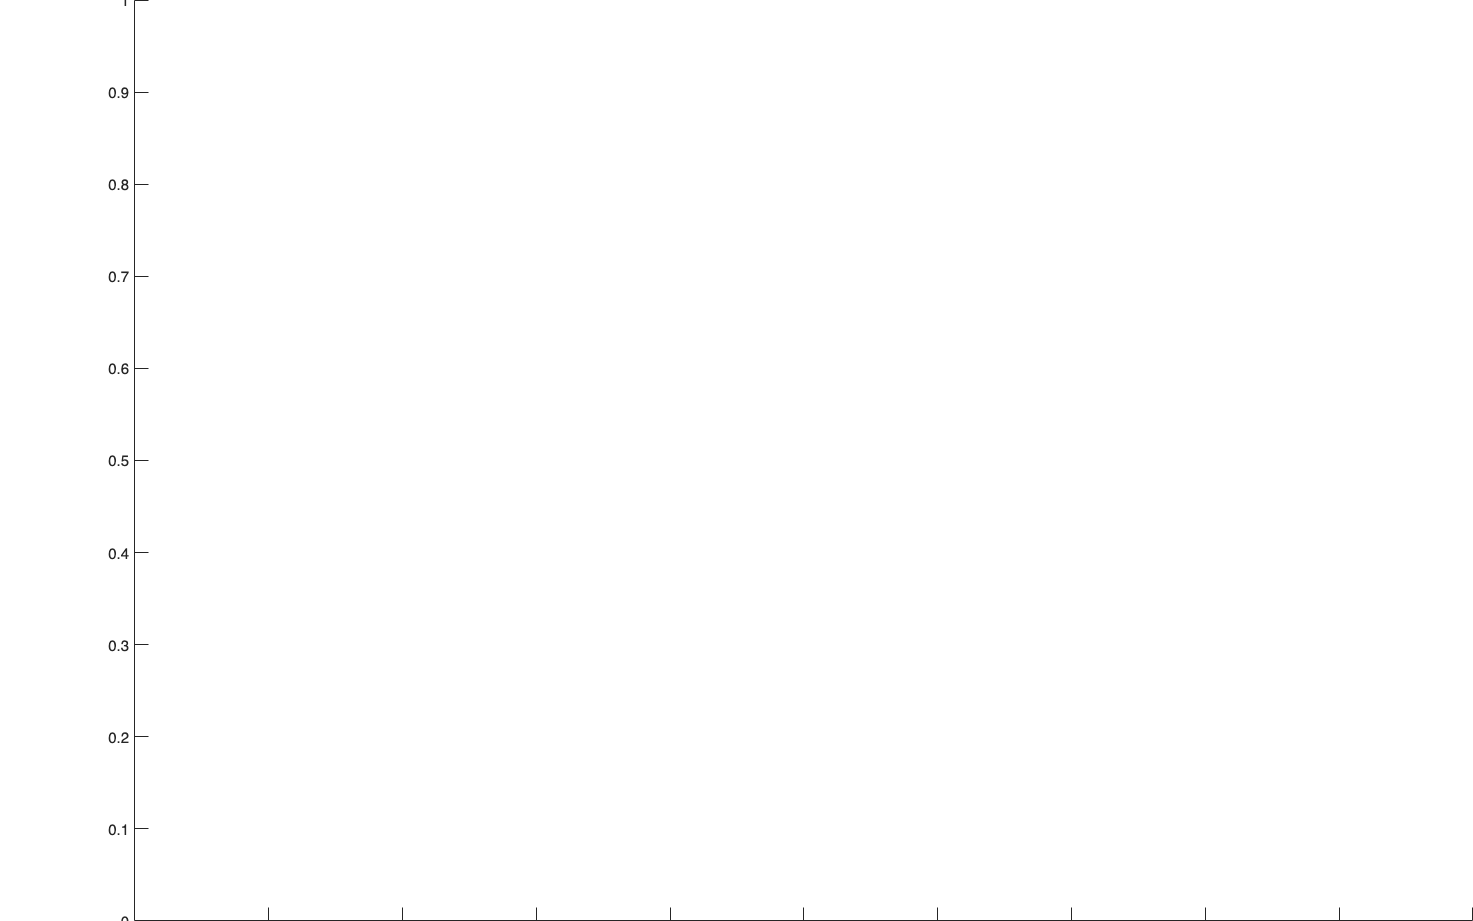

figure('position', get(0,'ScreenSize'));
axes('position', [0 0 1 1]);

legend('location','westoutside');
legend('hide');

%[x,y] = ginput;

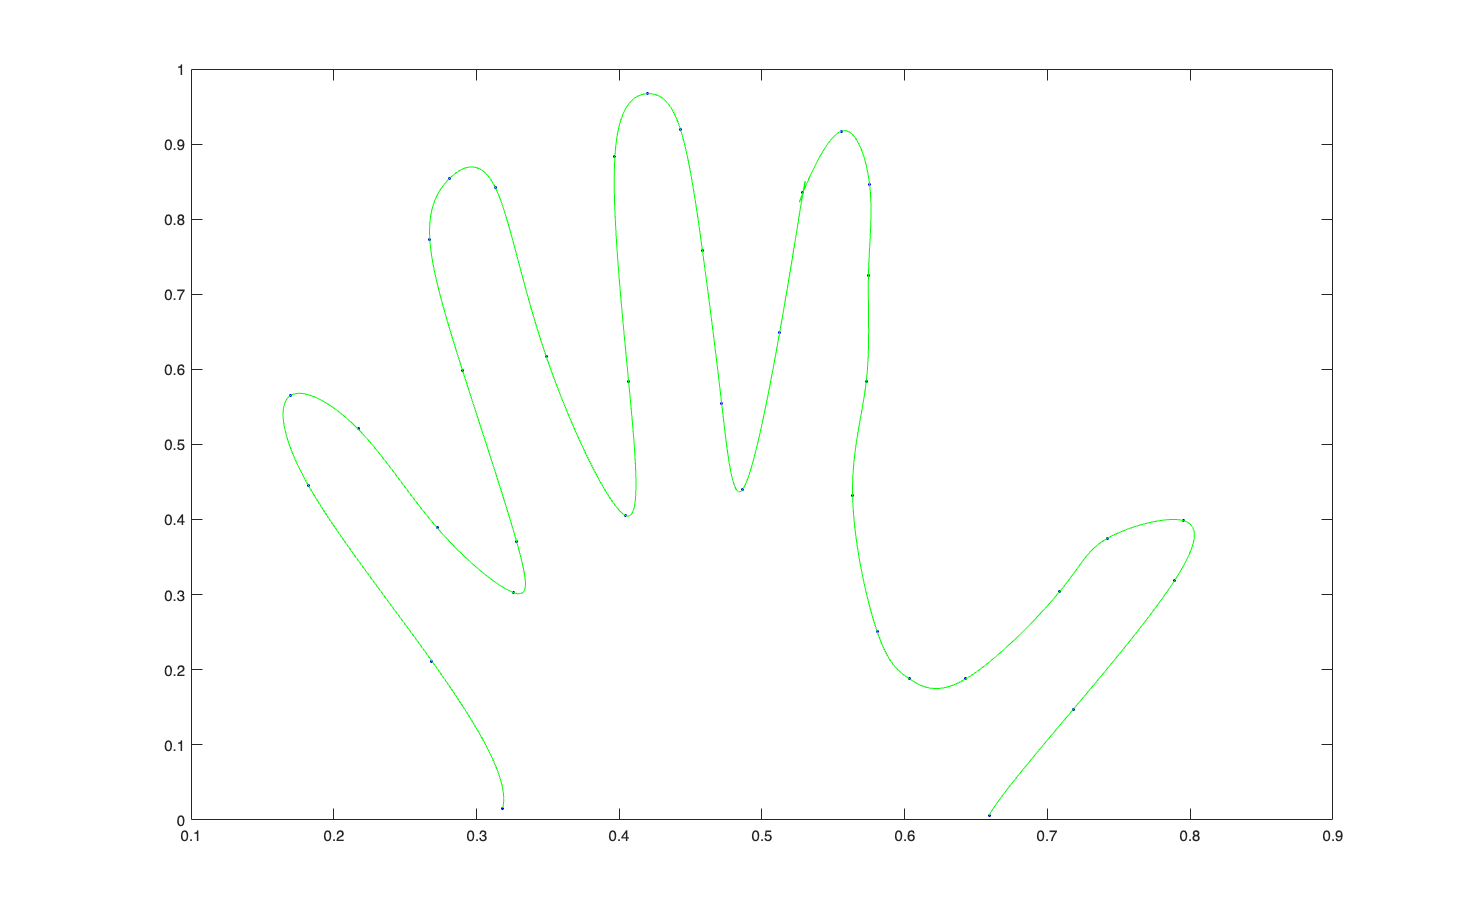

puntsX = x;
puntsY = y;

puntsNousX = unnamed(:,1); %és una variable que es troba al fitxer maPunts.mat
puntsNousY = unnamed(:,2);

n = length(puntsNousX);
s = (1:n)';
t = (1:.05:n)';
u = splinetx(s,puntsNousX,t);
v = splinetx(s,puntsNousY,t);
clf reset
plot(puntsNousX,puntsNousY,'b.',u,v,'g-');

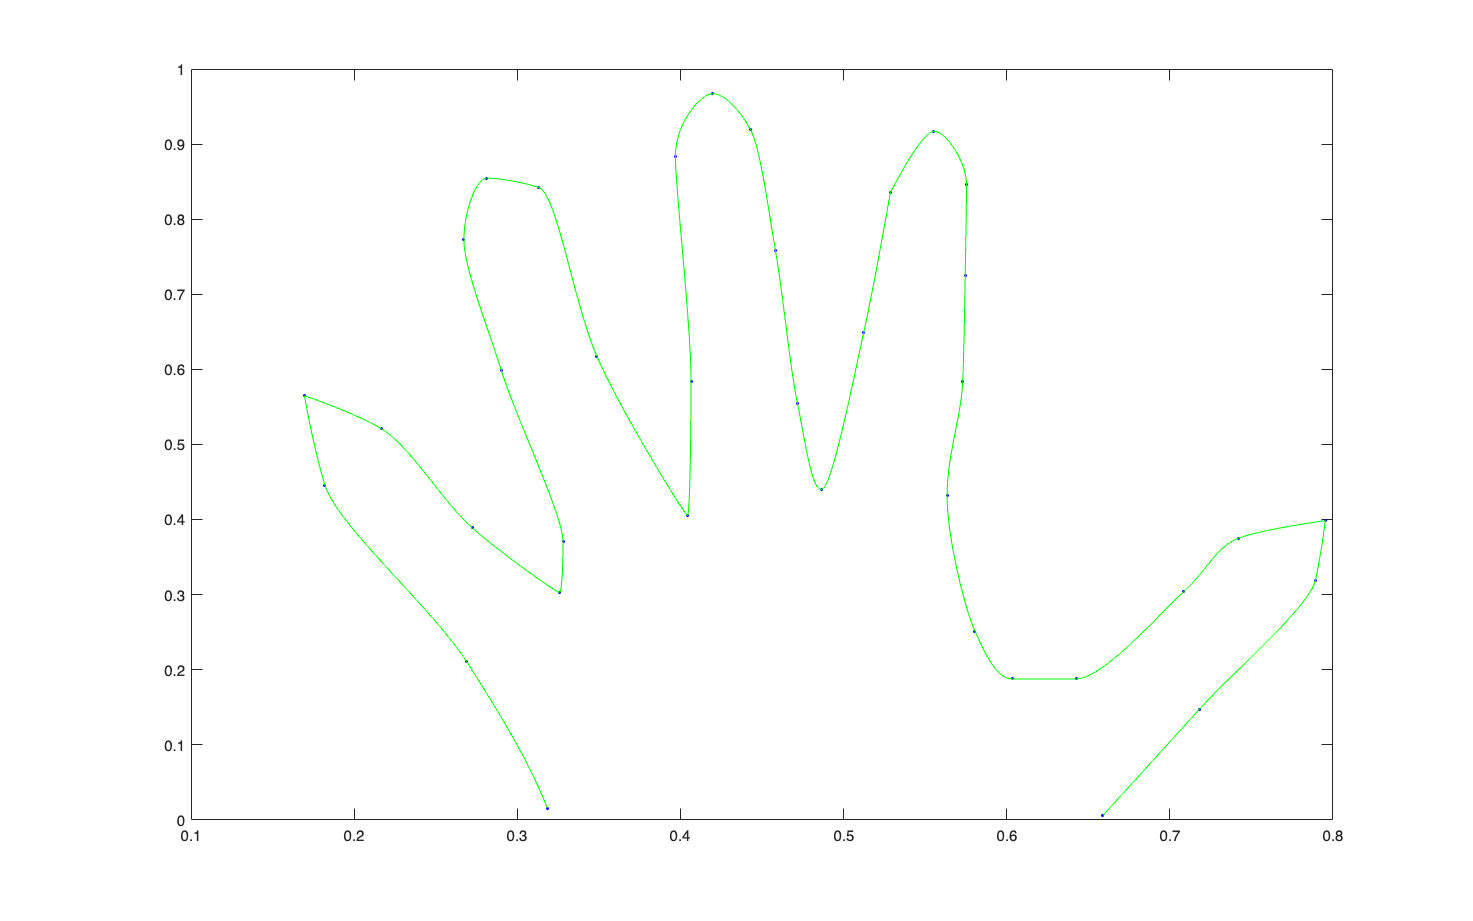


u2 = pchiptx(s,puntsNousX,t);
v2 = pchiptx(s,puntsNousY,t);
clf reset
plot(puntsNousX,puntsNousY,'b.',u2,v2,'g-');

**Apartat 2. **

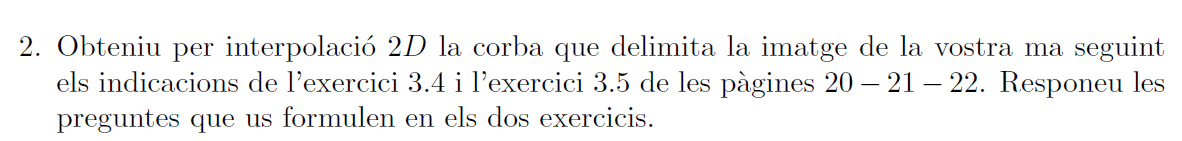

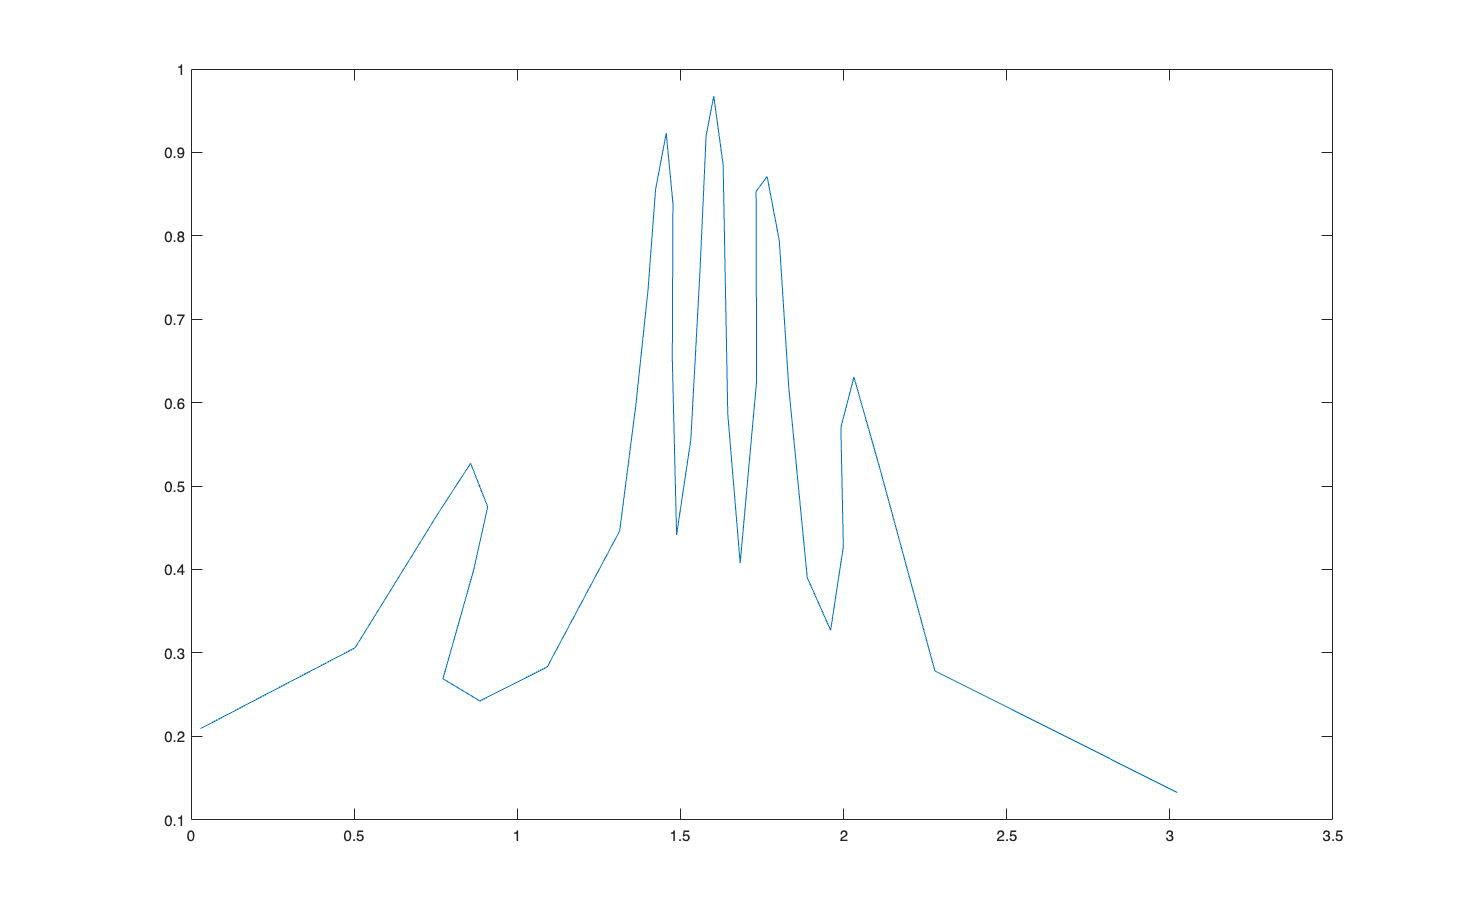

%punt vermell al mig del palmell
x0 = 0.45;
y0 = 0.0;

n = length(puntsNousX);
s = (1:n)';
t = (1:.05:n)';
u = splinetx(s,puntsNousX,t);
v = splinetx(s,puntsNousY,t);

puntsNousX = puntsNousX - x0;
puntsNousY = puntsNousY - y0;
theta = atan2(puntsNousY,puntsNousX);
r = sqrt(puntsNousX.^2+puntsNousY.^2);
plot(theta,r)

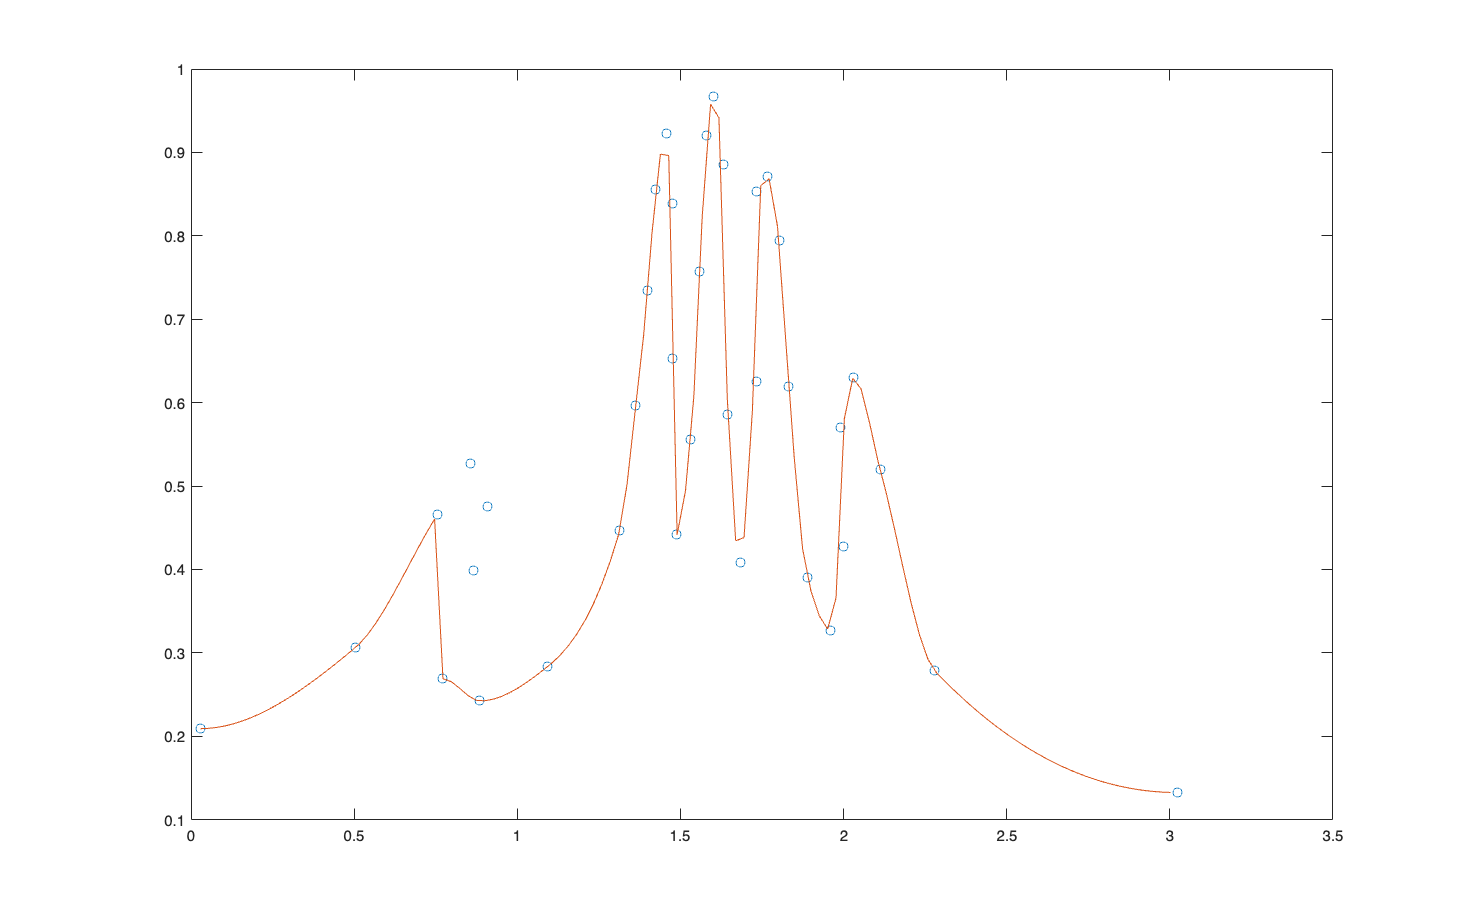


t = (theta(1):1/length(theta):theta(end))';
p = pchiptx(theta,r,t);
s = splinetx(theta,r,t);
plot(theta,r,'o',t,[p s],'-')

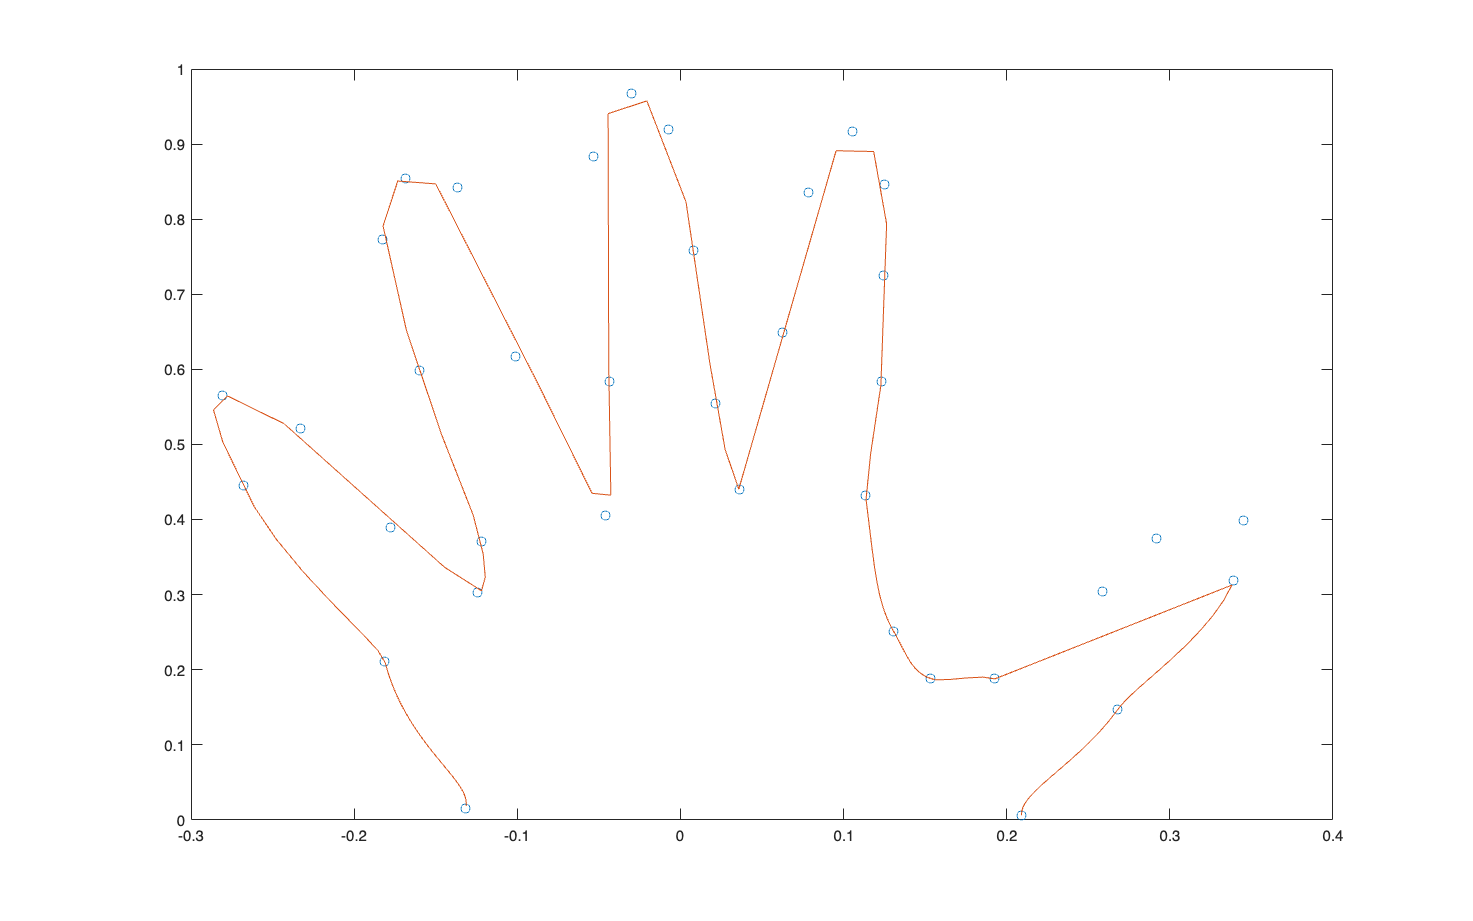


plot(puntsNousX,puntsNousY,'o',p.*cos(t),p.*sin(t),'-', s.*cos(t),s.*sin(t),'-')

3.4 Pchip vs Spline?

Prefereixo en aquest cas l'spline ja que tal i com es pot veure obtenim una imatge molt més definida i més suau de la mà. És a dir, la derivada segona de l'spline és continua i podem veure que si les dades consisteixen en valors d'una funció contínua l'spline produeix un resultat més precís. Conclusió extreta de: [https://es.mathworks.com/content/dam/mathworks/mathworks-dot-com/moler/interp.pdf](https://es.mathworks.com/content/dam/mathworks/mathworks-dot-com/moler/interp.pdf) (apartat 3.7)

La figura que es mostra està feta amb l'spline.

3.5 Quina aproximació és millor? Aquesta o la del darrer exercici?

L'aproximació més bona és que es realiza a l'apartat anterior.

**Apartat 3. **

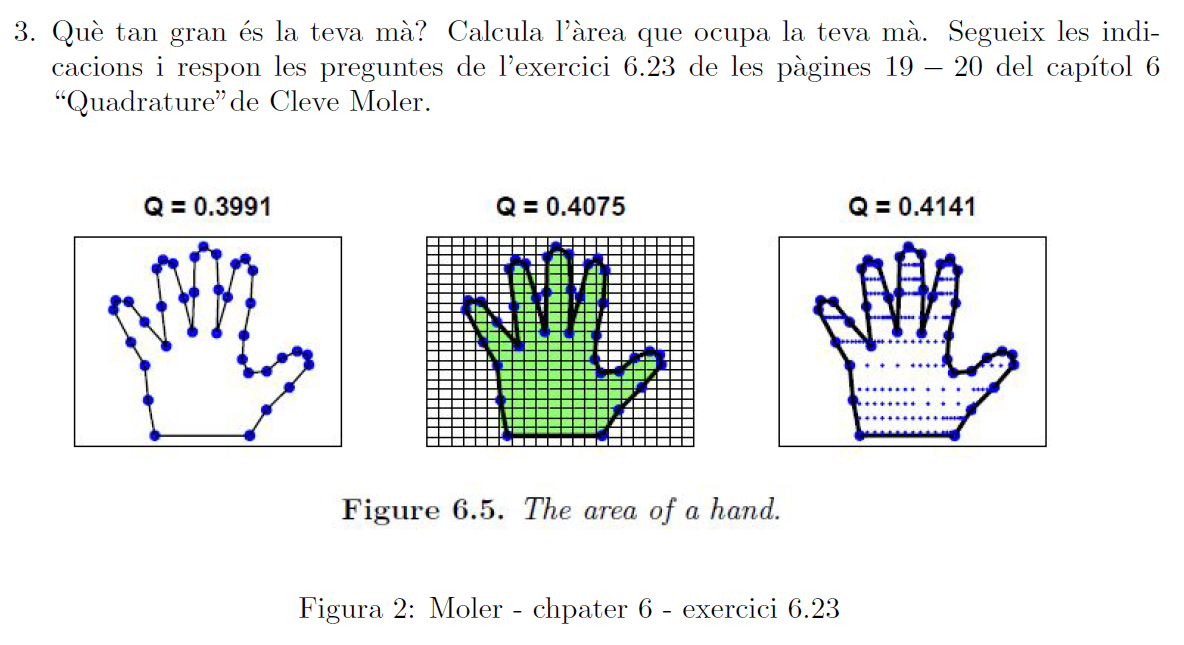

%Podem calcular l'àrea de 3 formes possibles:
%àrea del polígon
area = (puntsNousX'*puntsNousY([2:n 1]) - puntsNousX([2:n 1])'*puntsNousY)/2;

%simple quadratura
[u,v] = meshgrid(min(puntsNousX):0.1:max(puntsNousX),min(puntsNousY):0.1:max(puntsNousY));
k = inpolygon(u,v,puntsNousX,puntsNousY);
area2 = 0.1^2*nnz(k);

%R^2 quadratura adaptativa
area3 = dblquad(@(u,v)chi(u,v,puntsNousX,puntsNousY),min(puntsNousX),max(puntsNousX),min(puntsNousY),max(puntsNousY),5*(10)^-15);
%si posem epsilon peta i tarda molt

%mostrem els valors de l'àrea en una taula
array2table([area,area2,area3], 'VariableName',{'Àrea del polígon', 'Simple Quadratura', 'R^2 Quadratura Adaptativa'})

ans = 1×3 table
    Àrea del polígon    Simple Quadratura    R^2 Quadratura Adaptativa
    ________________    _________________    _________________________

       0.25482822              0.2               0.254580717019077    


function F = myfun(x)  
    F(1) = x(1)^2-10*x(1) + x(2)^2 + 8; %x(1) = x, x(2) = y
    F(2) = x(1)*x(2)^2 + x(1) - 10*x(2) + 8;
end

% Mètode de Newton per a funcions de dues variables
function valor = newtonModificat(F, DF, Z, n, tolF, tolZ, iteracions) 
    fz     = F(Z(1),Z(2)); 
    jacobianafz  = DF(Z(1),Z(2)); 

    valorf = Z(1); 
    valorz = Z(2);

    k = 0;
    while (k < n && (valorf > tolF || valorz > tolZ)) %si convergeix, concloem
        Y  = jacobianafz \ (-fz); %soluciona per y, o també fent la Jacobiana de F(x) (J : ℝⁿ → ℝⁿˣⁿ)
        
        vz = Z;
        Z  = vz + Y; %actualitzem estimació arrel
    
        k = k+1;
        if mod(k , iteracions) == 0 jacobianafz = DF(Z(1),Z(2)); end

        fz     = F(Z(1),Z(2));

        valorz = norm(Y);
        valorf = norm(fz);
    end
    
    valor = Z;

    disp(['Solució = ',num2str(Z')])
    disp(['tolF = ',num2str(valorf)])
    disp(['tolX = ',num2str(valorz)])
    disp(['Iteracions = ',num2str(k)])
end

% Mètode de Jacobi per a funcions de dues variables
function valor = newtonJacobi(F, DF, Z, iteracions, tolF, tolZ)
    fz  = F(Z(1),Z(2)); 
    jacobianafz = diag(diag(DF(Z(1),Z(2)))); 

    vf = Z(1); 
    vz = Z(2); 

    k  = 0;    
    while (k < iteracions && (vf > tolF || vz > tolZ))
        Y  = jacobianafz \ (-fz); %soluciona per y, o també fent la Jacobiana de F(x) (J : ℝⁿ → ℝⁿˣⁿ)
        
        pz = Z;
        Z  = pz + Y;  %actualitzem estimació arrel

        jacobianafz = diag(diag(DF(Z(1),Z(2)))); 
        fz    = F(Z(1),Z(2));

        vz = norm(Y);
        vf = norm(fz);

        k  = k + 1;
    end

    valor = Z;

    disp(['Solució = ',num2str(Z')]);
    disp(['tolF = ',num2str(vf)]);
    disp(['tolZ = ',num2str(vz)]);
    disp(['Iteracions = ',num2str(k)]);

end

% Mètode de Gauss Seidel per a funcions de dues variables
function valor = newtonGaussSeidel(F, DF, Z, iteracions, tolF, tolZ)
    fz    = F(Z(1),Z(2)); 
    jacobianafz = tril(DF(Z(1),Z(2))); 

    valorf = Z(1); 
    valorz = Z(2);

    k = 0;
    while (k < iteracions && (valorf > tolF || valorz > tolZ))
        y  = jacobianafz \ (-fz);
        
        pz  = Z;
        Z   = pz + y;

        jacobianafz    = tril(DF(Z(1),Z(2))); 
        fz       = F(Z(1),Z(2));

        valorz = norm(y);
        valorf = norm(fz);

        k = k + 1;
    end

    valor = Z;

    disp(['Solució = ',num2str(Z')]);
    disp(['tolF = ',num2str(tolF)]);
    disp(['tolZ = ',num2str(tolZ)]);
    disp(['Iteracions = ',num2str(k)]);
end


function valor = iteracioSimple(G, F, Z, iteracions, tolerancia)
    FZ   = F(Z(1),Z(2)); 

    tolF = 10^(-6); 
    tolZ = 10^(-6);

    k = 0; 
    while (k < iteracions && (tolF > tolerancia || tolZ > tolerancia))
        
        pz   = Z;
        Z    = G(Z(1),Z(2));

        tolF = norm(F(Z(1),Z(2)));
        tolZ = norm(Z-pz);
        
        k = k + 1;
    end
   
    valor = Z;

    disp(['Solució = ',num2str(Z')]);
    disp(['tolF = ',num2str(tolF)]);
    disp(['tolZ = ',num2str(tolZ)]);
    disp(['Iteracions = ',num2str(k)]);
end


function v = polyinterp(x,y,u)
%POLYINTERP  Polynomial interpolation.
%   v = POLYINTERP(x,y,u) computes v(j) = P(u(j)) where P is the
%   polynomial of degree d = length(x)-1 with P(x(i)) = y(i).
%   Copyright 2014 Cleve Moler
%   Copyright 2014 The MathWorks, Inc.
% Use Lagrangian representation.
% Evaluate at all elements of u simultaneously.
n = length(x);
v = zeros(size(u));
for k = 1:n
   w = ones(size(u));
   for j = [1:k-1 k+1:n]
      w = (u-x(j))./(x(k)-x(j)).*w;
   end
   v = v + w*y(k);
end
end


%la mà
function v = splinetx(x,y,u)
%SPLINETX  Textbook spline function.
%  v = splinetx(x,y,u) finds the piecewise cubic interpolatory
%  spline S(x), with S(x(j)) = y(j), and returns v(k) = S(u(k)).
%
%  See SPLINE, PCHIPTX.

%   Copyright 2014 Cleve Moler
%   Copyright 2014 The MathWorks, Inc.

%  First derivatives

   h = diff(x);
   delta = diff(y)./h;
   d = splineslopes(h,delta);

%  Piecewise polynomial coefficients

   n = length(x);
   c = (3*delta - 2*d(1:n-1) - d(2:n))./h;
   b = (d(1:n-1) - 2*delta + d(2:n))./h.^2;

%  Find subinterval indices k so that x(k) <= u < x(k+1)

   k = ones(size(u));
   for j = 2:n-1
      k(x(j) <= u) = j;
   end

%  Evaluate spline

   s = u - x(k);
   v = y(k) + s.*(d(k) + s.*(c(k) + s.*b(k)));
end
function d = splineslopes(h,delta)
%  SPLINESLOPES  Slopes for cubic spline interpolation.
%  splineslopes(h,delta) computes d(k) = S'(x(k)).
%  Uses not-a-knot end conditions.

%  Diagonals of tridiagonal system

   n = length(h)+1;
   a = zeros(size(h)); b = a; c = a; r = a;
   a(1:n-2) = h(2:n-1);
   a(n-1) = h(n-2)+h(n-1);
   b(1) = h(2);
   b(2:n-1) = 2*(h(2:n-1)+h(1:n-2));
   b(n) = h(n-2);
   c(1) = h(1)+h(2);
   c(2:n-1) = h(1:n-2);

%  Right-hand side

   r(1) = ((h(1)+2*c(1))*h(2)*delta(1)+ ...
          h(1)^2*delta(2))/c(1);
   r(2:n-1) = 3*(h(2:n-1).*delta(1:n-2)+ ...
              h(1:n-2).*delta(2:n-1));
   r(n) = (h(n-1)^2*delta(n-2)+ ...
          (2*a(n-1)+h(n-1))*h(n-2)*delta(n-1))/a(n-1);

%  Solve tridiagonal linear system

   d = tridisolve(a,b,c,r);
end

function x = tridisolve(a,b,c,d)
%   TRIDISOLVE  Solve tridiagonal system of equations.
%     x = TRIDISOLVE(a,b,c,d) solves the system of linear equations
%     b(1)*x(1) + c(1)*x(2) = d(1),
%     a(j-1)*x(j-1) + b(j)*x(j) + c(j)*x(j+1) = d(j), j = 2:n-1,
%     a(n-1)*x(n-1) + b(n)*x(n) = d(n).
%
%   The algorithm does not use pivoting, so the results might
%   be inaccurate if abs(b) is much smaller than abs(a)+abs(c).
%   More robust, but slower, alternatives with pivoting are:
%     x = T\d where T = diag(a,-1) + diag(b,0) + diag(c,1)
%     x = S\d where S = spdiags([[a; 0] b [0; c]],[-1 0 1],n,n)

%   Copyright 2014 Cleve Moler
%   Copyright 2014 The MathWorks, Inc.

x = d;
n = length(x);

for j = 1:n-1
   mu = a(j)/b(j);
   b(j+1) = b(j+1) - mu*c(j);
   x(j+1) = x(j+1) - mu*x(j);
end

x(n) = x(n)/b(n);
for j = n-1:-1:1
   x(j) = (x(j)-c(j)*x(j+1))/b(j);
end
end

function v = pchiptx(x,y,u)
%PCHIPTX  Textbook piecewise cubic Hermite interpolation.
%  v = pchiptx(x,y,u) finds the shape-preserving piecewise cubic
%  interpolant P(x), with P(x(j)) = y(j), and returns v(k) = P(u(k)).
%
%  See PCHIP, SPLINETX.
 
%  First derivatives
 
   h = diff(x);
   delta = diff(y)./h;
   d = pchipslopes(h,delta);

%  Piecewise polynomial coefficients

   n = length(x);
   c = (3*delta - 2*d(1:n-1) - d(2:n))./h;
   b = (d(1:n-1) - 2*delta + d(2:n))./h.^2;

%  Find subinterval indices k so that x(k) <= u < x(k+1)

   k = ones(size(u));
   for j = 2:n-1
      k(x(j) <= u) = j;
   end

%  Evaluate interpolant

   s = u - x(k);
   v = y(k) + s.*(d(k) + s.*(c(k) + s.*b(k)));

end
% -------------------------------------------------------

function d = pchipslopes(h,delta)
%  PCHIPSLOPES  Slopes for shape-preserving Hermite cubic
%  interpolation.  pchipslopes(h,delta) computes d(k) = P'(x(k)).

%  Slopes at interior points
%  delta = diff(y)./diff(x).
%  d(k) = 0 if delta(k-1) and delta(k) have opposites signs
%         or either is zero.
%  d(k) = weighted harmonic mean of delta(k-1) and delta(k)
%         if they have the same sign.

   n = length(h)+1;
   d = zeros(size(h));
   k = find(sign(delta(1:n-2)).*sign(delta(2:n-1)) > 0) + 1;
   w1 = 2*h(k)+h(k-1);
   w2 = h(k)+2*h(k-1);
   d(k) = (w1+w2)./(w1./delta(k-1) + w2./delta(k));

%  Slopes at endpoints

   d(1) = pchipendpoint(h(1),h(2),delta(1),delta(2));
   d(n) = pchipendpoint(h(n-1),h(n-2),delta(n-1),delta(n-2));
end
% -------------------------------------------------------

function d = pchipendpoint(h1,h2,del1,del2)
%  Noncentered, shape-preserving, three-point formula.
   d = ((2*h1+h2)*del1 - h1*del2)/(h1+h2);
   if sign(d) ~= sign(del1)
      d = 0;
   elseif (sign(del1) ~= sign(del2)) & (abs(d) > abs(3*del1))
      d = 3*del1;
   end
end


%quadratura
function k = chi(u,v,x,y)
if all(size(u) == 1), u = u(ones(size(v))); 
end
if all(size(v) == 1), v = v(ones(size(u))); 
end
k = inpolygon(u,v,x,y);
end